# **Numerical properties of a reconstruction**

**Authors: Laurent Heirendt, Ronan M.T. Fleming, Luxembourg Centre for Systems Biomedicine**

**Reviewers: Sylvain Arreckx, Thomas Pfau**

## Introduction

During this tutorial, you will learn how to determine and explore the numerical properties of a stoichiometric matrix. The numerical properties are key to analyzing the metabolic reconstruction at hand, to select the appropriate solver, or to determine incoherences in the network. 

You will also be able to learn more about the definitions of the various numerical characteristics. This tutorial is particularly useful when you have a multi-scale model and are facing numerical issues when performing flux balance analysis or any of its associated variants.

## MATERIALS - EQUIPMENT SETUP

Please ensure that The COBRA Toolbox has been properly installed and initialized. There are no specific solvers required to run this tutorial.

## PROCEDURE 

TIMING: 5 seconds - several hours (depending on the model size)

**Define the name of the model**

Throughout this tutorial, we will use the *E.coli core* model [1]. It is generally good practice to define the name of the file that contains the model, the variable that contains the model structure, as well as the name of the stoichiometric matrix as separate variables. We here suppose that within the `modelFile`, there is a structure named `modelName` with a field `matrixName` that contains the stoichiometric matrix `S` (or `A`).

% define the filename of the model
modelFile = 'ecoli_core_model.mat';

% define the name of model structure
modelName = 'model';

% define the fieldname of the stoichiometric matrix
matrixName = 'S';

**Load the stoichiometric matrix**

In order to use the model, we need to load the `modelFile` that contains a COBRA model structure  `modelName`:

% load the modelName structure from the modelFile
load(modelFile, modelName);

Some models contain stoichiometric matrices with a different name (commonly coupled models). By default, the stoichiometric matrix is denoted `S`.

% select the matrix
S = model.S;
if isfield(model, matrixName) == 1 && strcmp(matrixName, 'A') == 1
    S = model.A;
end

**Basic numerical characteristics**

The **number of elements** represents the total number of entries in the stoichiometric matrix (including zero elements). This number is equivalent to the product of the number of reactions and the number of metabolites.

The number of rows is equivalent to the **number of metabolites** in the metabolic network. The number of columns corresponds to the **number of biochemical reactions** in the network.

% determine the number of reactions and metabolites in A
[nMets, nRxns] = size(S)

nMets = 72

nRxns = 95

% determine the number of elements in A
nElem = numel(S)  % Nmets * Nrxns

nElem = 6840

The total number of nonzero elements corresponds to the total number of nonzero entries in the stoichiometric matrix (excluding zero elements).

% determine the number of nonzero elements in A
nNz = nnz(S)

nNz = 360

**Sparsity and Density**

The **sparsity ratio** corresponds to the ratio of the number of zero elements and the total number of elements. The sparser a stoichiometric matrix, the fewer metabolites participate in each reaction. The sparsity ratio is particularly useful to compare models by how many metabolites participate in each reaction.

Similarly, the **complementary sparsity ratio** is calculated as the difference of 100 and the sparsity ratio expressed in percent, and is the ratio of the number of nonzero elements and the total number of elements.

% determine the sparsity ratio of S (in percent)
sparsityRatio = (1 - nNz / nElem) * 100.0  % [%]

sparsityRatio = 94.7368

% determine the complementary sparsity ratio (in percent)
compSparsityRatio = 100.0 - sparsityRatio  % [%]

compSparsityRatio = 5.2632

The** average column density **corresponds to the ratio of the number of nonzero elements in each column and the total number of metabolites. The average column density corresponds to the arithmetic average of all the column densities (sum of all the column densities divided by the number of reactions).

% add the number of non-zeros in each column (reaction)
colDensityAv = 0;
for i = 1:nRxns
    colDensityAv = colDensityAv + nnz(S(:, i));
end

% calculate the arithmetic average number of non-zeros in each column
colDensityAv = colDensityAv / nRxns   % [-]

colDensityAv = 3.7895

The average column density provides a measure of how many stoichiometric coefficients participate in each biochemical reaction in average.

The **relative column density** corresponds to the ratio of the number of nonzero elements in each column and the total number of metabolites. The relative column density corresponds to the average column density divided by the total number of metabolites (expressed in percent). The relative column density may also be expressed as parts-per-million [ppm] for large-scale or huge-scale models.

% determine the density proportional to the length of the column
colDensityRel = colDensityAv / nMets * 100  % [%]

colDensityRel = 5.2632

The relative column density indicates how many metabolites are being used in average in each reaction relative to the total number of metabolites in the metabolic network.

**Sparsity Pattern (spy plot)**

The visualisation of the sparsity pattern is useful to explore the matrix, spot inconsistencies, or identify patterns visually. In addition to the standard sparsity pattern, the magnitude of the elements of the stoichiometric matrix (stoichiometric coefficients) is shown as proportional to the size of the dot.

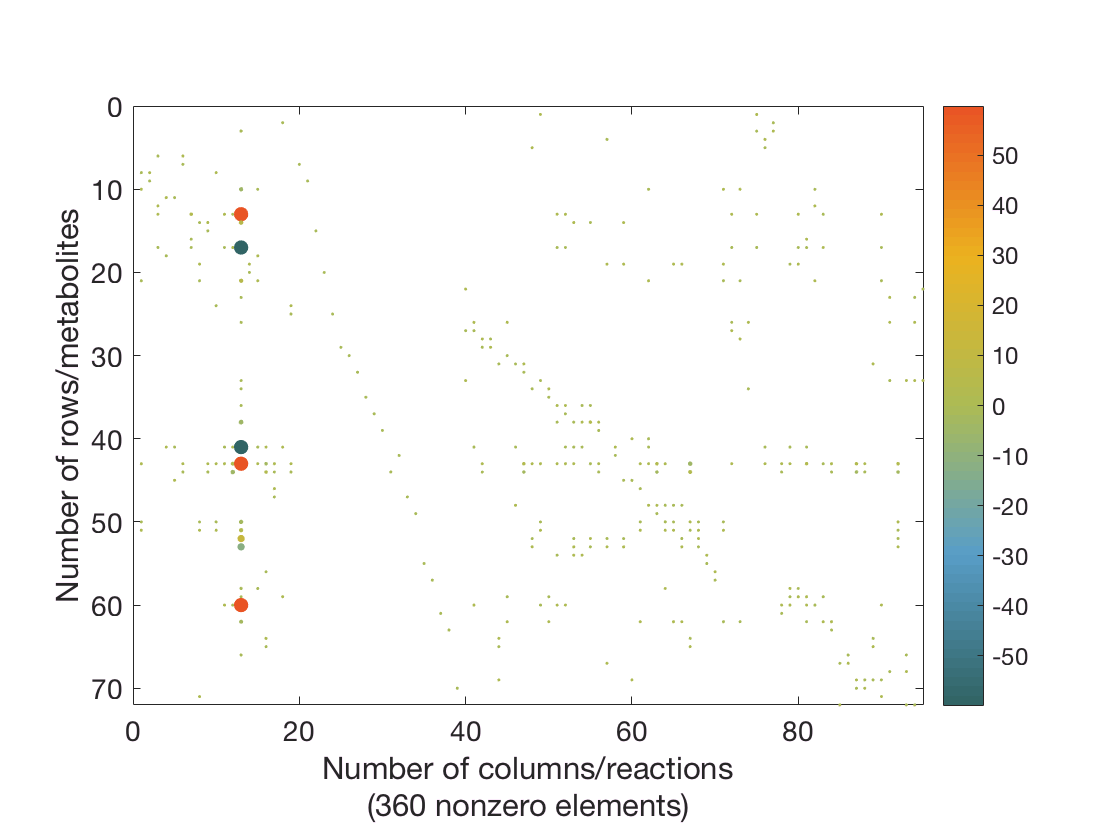

% print a colorful spy map of the S matrix
spyc(S, colormap(advancedColormap('cobratoolbox')));

% set the font size of the current figure axes
set(gca, 'fontsize', 14);

In the case of the *E.coli core* model [1],  the biomass reaction is clearly visible (reaction number 13) due to its large amount of metabolites (dots in the column) and large coefficients (size of the dots). Also, the metabolites with large stoichiometric coefficients can be easily determined based on their dot size.

**Rank**

The **rank** of a stoichiometric matrix is the maximum number of linearly independent rows and is equivalent to the number of linearly independent columns. The rank is a measurement of how many reactions and metabolites are linearly independent. The rank is preferably calculated using the LUSOL solver [3].

% determine the rank of the stoichiometric matrix
rankS = getRankLUSOL(S)

rankS = 67

The **rank deficiency** of the stoichiometric matrix is a measure of how many reactions and metabolites are not linearly dependent, and expressed as the ratio of the rank of the stoichiometric matrix to the theoretical full rank.

% calculate the rank deficiency (in percent)
rankDeficiencyS = (1 - rankS / min(nMets, nRxns)) * 100  % [%]

rankDeficiencyS = 6.9444

**Singular Values and Condition Number**

A singular value decomposition of the stoichiometric matrix is the decomposition into orthonormal matrices $U$ (of dimension `nMets` by `nMets`) and $V$ (of dimension `nRxns` by `nRxns`), and a matrix with diagonal elements $D$ such that $S = UDV^T$.

Note that the calculation of singular values is numerically expensive, especially for large stoichiometric matrices.

% calculate the singular values
svVect = svds(S, rankS);

The `svds() `function returns the number of singular values specified in the second argument of the function. As most stoichiometric matrices are rank deficient, some singular values are zero (or within numerical tolerances). The cut-off is located at the rank of the stoichiometric matrix. 

% determine the vector with all singular values (including zeros)
svVectAll = svds(S, min(nMets, nRxns));

The singular values and their cut-off can be illustrated as follows:

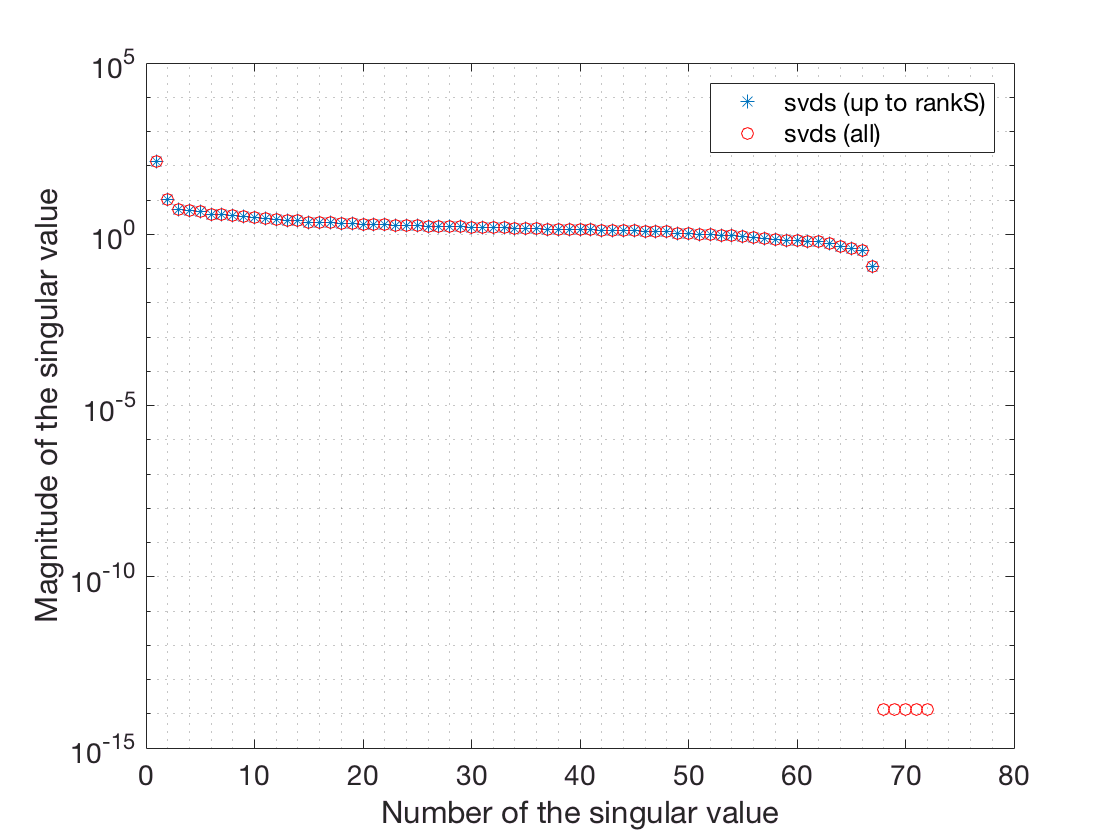

% plot the singular values
figure;

% plot the singular values up to rankS
semilogy(linspace(1, length(svVect), length(svVect)), svVect, '*');

% plot all singular values
hold on;
semilogy(linspace(1, length(svVectAll), length(svVectAll)), svVectAll, 'ro');

% set the font size of the current figure axes, show a legend and minor grid axes
set(gca, 'fontsize', 14);
legend('svds (up to rankS)', 'svds (all)')
grid minor;

% set the label
xlabel('Number of the singular value');
ylabel('Magnitude of the singular value');

hold off;

The** maximum singular** value is the largest element on the diagonal matrix obtained from singular value decomposition. Similarly, the **minimum singular value** is the smallest element on the diagonal matrix obtained from singular value decomposition. Only singular values greater than zero (numbered from `1` to `rank(S)`) are of interest.

% determine the maximum and minimum singular values
maxSingVal = svVect(1) % first value of the vector with singular values

maxSingVal = 135.5764

minSingVal = svVect(rankS) % smallest non-zero singular value

minSingVal = 0.1161

Alternatively, if the rank of the stoichiometric matrix `S` is not known, the built-in functions can also be used: 

maxSingValBuiltIn = svds(S, 1)

maxSingValBuiltIn = 135.5764

minSingValBuiltIn = svds(S, 1, 'smallestnz')

minSingValBuiltIn = 0.1161

The **condition number** of the stoichiometric matrix is the ratio of the maximum and minimum singular values. The higher this ratio, the more ill-conditioned the stoichiometric matrix is (numerical issues) and, generally, the longer the simulation time is.

% determine the condition number
condNumber = maxSingVal / minSingVal

condNumber = 1.1676e+03

**Summary of model characteristics**

The following numerical properties have been calculated:

- **Number of elements**: represents the total number of entries in the stoichiometric matrix (including zero elements). This number is equivalent to the product of the number of reactions and the number of metabolites.

- **Number of nonzero elements**: represents the total number of nonzero entries in the stoichiometric matrix (excluding zero elements).

- **Sparsity ratio**: ratio of the number of zero elements and the total number of elements. The sparser a stoichiometric matrix, the fewer metabolites participate in each reaction. The sparsity ratio is particularly useful to compare models by how many metabolites participate in each reaction.

- **Complementary sparsity ratio**: calculated as the difference of one and the sparsity ratio, and is the ratio of the number of nonzero elements and the total number of elements.

- **Average column density**: corresponds to the ratio of the number of nonzero elements in each column and the total number of metabolites. The average column density corresponds to the arithmetic average of all the column densities (sum of all the column densities divided by the number of reactions).

- **Relative column density**: corresponds to the ratio of the number of nonzero elements in each column and the total number of metabolites. The relative column density corresponds to the average column density divided by the total number of metabolites (expressed in parts-per-million (ppm)).

- **Rank**: the rank of a stoichiometric matrix is the maximum number of linearly independent rows and is equivalent to the number of linearly independent columns. The rank is a measurement of how many reactions and metabolites are linearly independent.

- **Rank deficiency**: the rank deficiency of the stoichiometric matrix is a measure of how many reactions and metabolites are linearly dependent, and expressed as the ratio of the rank of the stoichiometric matrix to the theoretical full rank.

- **Maximum singular value**: the largest element on the diagonal matrix obtained from singular value decomposition.

- **Minimum singular value**: the smallest element on the diagonal matrix obtained from singular value decomposition.

- **Condition number**: the condition number of the stoichiometric matrix is the ratio of the maximum and minimum singular values. The higher this ratio, the more ill-conditioned the stoichiometric matrix is (numerical issues).

fprintf([' --- SUMMARY ---\n',...
    'Model file/Model name/Matrix name    %s/%s/%s\n',...
    'Size is [nMets, nRxns]               [%d, %d]\n',...
    'Number of elements:                  %d \n',...
    'Number of nonzero elements:          %d \n',...
    'Sparsity ratio [%%]:                  %1.2f \n',...
    'Complementary sparsity ratio [%%]     %1.2f \n', ...
    'Average column density [ppm]:        %1.2f \n',...
    'Relative column density [ppm]:       %1.2f \n',...
    'Rank:                                %d \n',...
    'Rank deficiency [%%]:                 %1.2f \n',...
    'Maximum singular value:              %1.2f \n',...
    'Minimum singular value:              %1.2f \n',...
    'Condition number:                    %1.2f \n',...
    ],...
    modelFile, modelName, matrixName, nMets, nRxns, nElem, nNz, sparsityRatio, ...
    compSparsityRatio, colDensityAv, colDensityRel, rankS, rankDeficiencyS, ...
    maxSingVal, minSingVal, condNumber);

 --- SUMMARY ---
Model file/Model name/Matrix name    ecoli_core_model.mat/model/S
Size is [nMets, nRxns]               [72, 95]
Number of elements:                  6840 
Number of nonzero elements:          360 
Sparsity ratio [%]:                  94.74 
Complementary sparsity ratio [%]     5.26 
Average column density [ppm]:        3.79 
Relative column density [ppm]:       5.26 
Rank:                                67 
Rank deficiency [%]:                 6.94 
Maximum singular value:              135.58 
Minimum singular value:              0.12 
Condition number:                    1167.63 


**Scaling**

The scaling estimate is based on the order of magnitude of the ratio of the maximum and minimum scaling coefficients, which are determined such that the scaled stoichiometric matrix has entries close to unity. In order to investigate the scaling of the stoichiometric matrix and provide an estimate of the most appropriate precision of the solver to be used, the following quantities should be calculated:

- **Estimation level: **The estimation level, defined by the parameter scltol provides a measure of how accurate the estimation is. The estimation level can be *crude*, *medium*, or *fine*.

- **Size of the matrix: **The size of the matrix indicates the size of the metabolic network, and is broken down into number of metabolites and number of reactions.

- **Stoichiometric coefficients:** The maximum and minimum values of the stoichiometric matrix provide a range of the stoichiometric coefficients and are determined based on all elements of the stoichiometric matrix. Their ratio (and its order of magnitude) provides valuable information on the numerical difficulty to solve a linear program.

- **Lower bound coefficients: **The maximum and minimum values of the lower bound vector provide a range of the coefficients of the lower bound vector. Their ratio (and its order of magnitude) provides valuable information on the numerical difficulty to solve a linear program.

- **Upper bound coefficients: **The maximum and minimum values of the upper bound vector provide a range of the coefficients of the upper bound vector. Their ratio (and its order of magnitude) provides valuable information on the numerical difficulty to solve a linear program.

- **Row scaling coefficients: **The row scaling coefficients are the scaling coefficients required to scale each row closer to unity. The maximum and minimum row scaling coefficients provide a range of row scaling coefficients required to scale the stoichiometric matrix row-wise. Their ratio (and its order of magnitude) provides valuable information on the numerical difficulty to solve a linear program. 

- **Column scaling coefficients: **The column scaling coefficients are the scaling coefficients required to scale each column closer to unity. The maximum and minimum column scaling coefficients provide a range of column scaling coefficients required to scale the stoichiometric matrix column-wise. Their ratio (and its order of magnitude) provides valuable information on the numerical difficulty to solve a linear program.

The scaling properties of the stoichiometric matrix can be determined using:

[precisionEstimate, solverRecommendation] = checkScaling(model);


 ------------------------ Scaling summary report ------------------------

 Name of model:                                Ecoli_core_model
 Estimation level:                             fine (scltol = 1.00)
 Name of matrix:                               S
 Size of matrix:
        * metabolites:                         72
        * reactions:                           95
 Stoichiometric coefficients:
        * Minimum (absolute non-zero value):   7.09e-02
        * Maximum (absolute non-zero value):   5.98e+01
 Lower bound coefficients:
        * Minimum (absolute non-zero value):   8.39e+00
        * Maximum (absolute non-zero value):   1.00e+03
 Upper bound coefficients:
        * Minimum (absolute non-zero value):   1.00e+03
        * Maximum (absolute non-zero value):   1.00e+03
 Row scaling coefficients:
        * Minimum:                             2.66e-01 (row #: 26)
        * Maximum:                             7.73e+00 (row #: 13)
 Column scaling coefficients:
        * Min

The `precisionEstimate` yields a recommended estimate of the precision of the solver:

precisionEstimate

precisionEstimate = double

The solver recommendation is provided in `solverRecommendation` as a cell array that  can be used programmatically:

solverRecommendation

solverRecommendation =     'glpk'    'gurobi'    'ibm_cplex'    'matlab'    'mosek'    'pdco'    'qpng'    'lp_solve'


In order to see the effect of scaling, let us consider the ME model [2]:

% load the modelName structure from the modelFile
load('ME_matrix_GlcAer_WT.mat', 'modelGlcOAer_WT');

The scaling can be checked as follows:

[precisionEstimate, solverRecommendation] = checkScaling(modelGlcOAer_WT);


 ------------------------ Scaling summary report ------------------------

 Estimation level:                             fine (scltol = 1.00)
 Name of matrix:                               S
 Size of matrix:
        * metabolites:                         68298
        * reactions:                           76664
 Stoichiometric coefficients:
        * Minimum (absolute non-zero value):   5.50e-05
        * Maximum (absolute non-zero value):   8.01e+05
 Lower bound coefficients:
        * Minimum (absolute non-zero value):   1.00e+06
        * Maximum (absolute non-zero value):   1.00e+09
 Upper bound coefficients:
        * Minimum (absolute non-zero value):   5.54e+00
        * Maximum (absolute non-zero value):   1.00e+09
 Row scaling coefficients:
        * Minimum:                             1.67e-03 (row #: 24548)
        * Maximum:                             7.90e+04 (row #: 66206)
 Column scaling coefficients:
        * Minimum:                             3.47e-04 (column #

In this case, the `solverRecommendation` is:

solverRecommendation

solverRecommendation =     'dqqMinos'    'quadMinos'


The solver then can be set as as suggested to use the quad-precision solver:

% changeCobraSolver(solverRecommendation{1});

Note that the timing for obtaining a solution using a quad-precision solver is very different than obtaining the solution using a double-precision solver. 

## EXPECTED RESULTS

The expected result is a summary table with relevant numerical characteristics and a recommendation of the precision of the solver.

## TROUBLESHOOTING

If any numerical issues arise (e.g., infeasible solution status after performing flux balance analysis, or too long simulation times) when using a double precision solver, then a higher precision solver should be tested. For instance, a double precision solver may incorrectly report that an ill-scaled optimisation problem is infeasible although it actually might be feasible for a higher precision solver. 

In some cases,  the precision recommendation might not be accurate enough and a double precision solver might lead to inaccurate results. Try a quad precision solver in order to confirm the results when in doubt.

The `checkScaling()` function may be used on all operating systems, but the `'dqqMinos'` interface is only available on UNIX operating systems. If the `'dqqMinos'` interface is not working as intended, the binaries might not be compatible (raise an issue if they are not by providing the output of `generateSystemConfigReport`). Make sure that all relevant system requirements are satisfied before trying to use the `'dqqMinos'` solver interface.

In case the `'dqqMinos' `interface reports an error when trying to solve the linear program, there might be an issue with the model itself.

## References

[1] Reconstruction and Use of Microbial Metabolic Networks: the Core Escherichia coli Metabolic Model as an Educational Guide by Orth, Fleming, and Palsson (2010)

[2] Multiscale modeling of metabolism and macromolecular synthesis inE. coli and its application to the evolution of codon usage, Thiele et al., PLoS One, 7(9):e45635 (2012)

[2] P. E. Gill, W. Murray, M. A. Saunders and M. H. Wright (1987). Maintaining LU factors of a general sparse matrix, Linear Algebra and its Applications 88/89, 239-270.